**ECEN 470: PS02: Problem 3.26: Seth Ricks**

For the unity feedback system shown in Fig. 3.55, specify the gain and pole location of the compensator so the overall closed-loop response to a unit-step input has an overshoot of no more than 25%, and a 1% settling time of no more than 0.1 sec. Verify your design using Matlab.

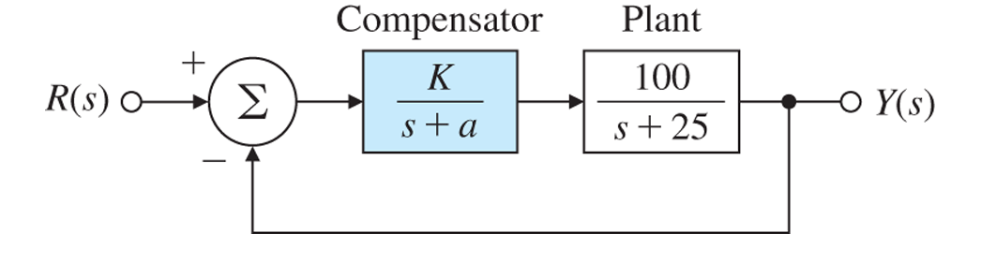

(I got k =113.06 and a = 67.06 on paper)

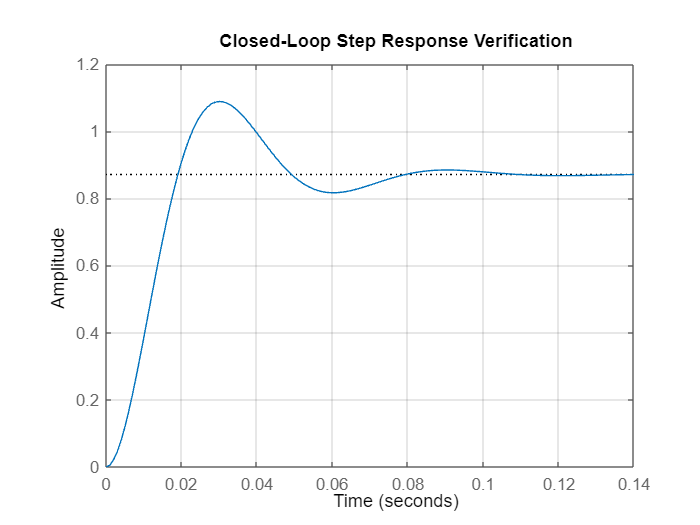

% This code was generated by AI, and edited by Seth Ricks
% Define the Laplace variable s
s = tf('s');

K = 113.06;   
a = 67.06;   % (corresponds to pole at s = -a)

C = K / (s + a);       % Compensator TF
P = 100 / (s + 25);    % Plant TF

% Form the closed-loop system (Unity feedback)
T = feedback(C * P, 1);

% Plot the step response to verify specifications
figure;
step(T);
grid on;
title('Closed-Loop Step Response Verification');


% Check step response characteristics automatically
info = stepinfo(T, SettlingTimeThreshold=0.01); % 1% settling time
disp('--- Step Response Metrics ---');

--- Step Response Metrics ---


disp(['Overshoot (%): ', num2str(info.Overshoot)]);

Overshoot (%): 24.9698


disp(['1% Settling Time (sec): ', num2str(info.SettlingTime)]);

1% Settling Time (sec): 0.09918
